# 共通設定

dt = 0.01;  % サンプリング時間

# 群れ制御

t_end = 10; % シミュレーション時間

p_init = [0.8, -0.2, -0.5, 0.3, 0];    % 初期位置
robot_num = length(p_init);

k = 1; % フィードバックゲイン
L = eye(5); 

## シミュレーションの実行

slx_model_name = 'flocking_control';
out = sim(slx_model_name);

## 結果の表示

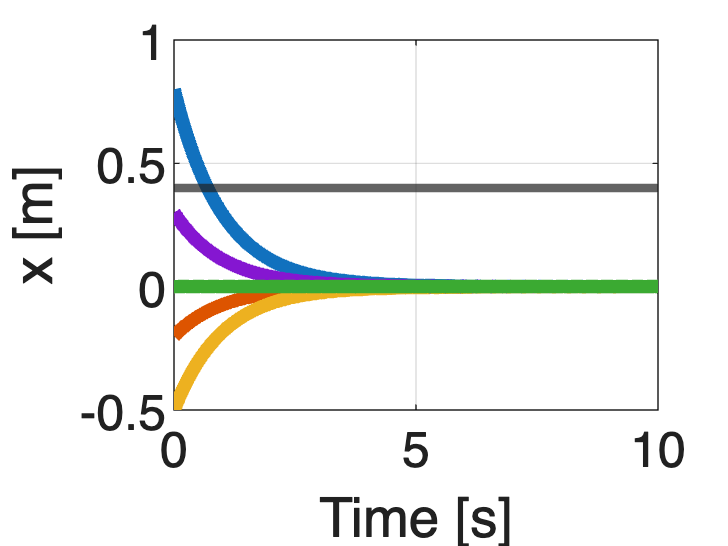

figure
plot(out.tout, out.position, "LineWidth", 5)
hold on
yline(0.4, "LineWidth", 3)
fontsize(18, "points")
xlabel('Time [s]')
ylabel('x [m]')
grid on

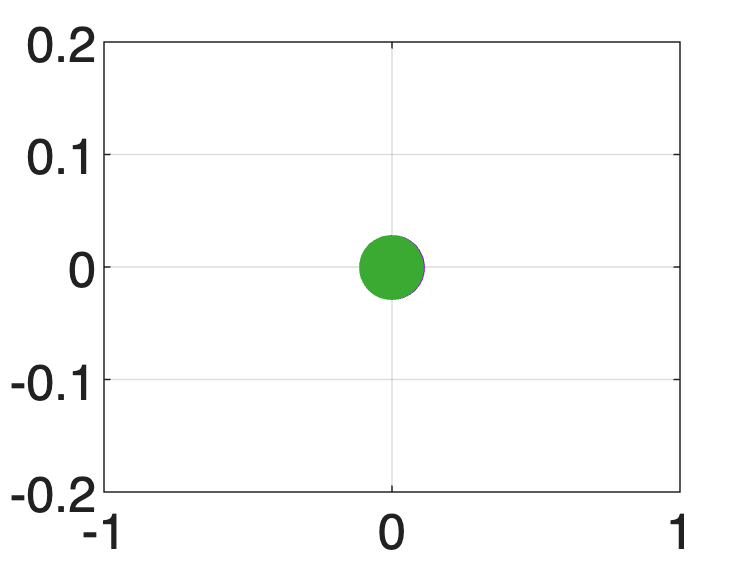


h = cell(1, robot_num);
figure
for i=1:robot_num
    h{i} = plot(p_init(i), 0, ".", "MarkerSize", 70);
    hold on
end
grid on
hold off
fontsize(18, "points")
xlim([-1, 1]); ylim([-0.2, 0.2])
for i=1:1:length(out.tout)
    for j=1:robot_num
        h{j}.XData = out.position(i,j);
    end
    pause(dt);
    drawnow limitrate; 
end